# problem set 1

## problem 1

%part a
    a = [1 + 1i 1 + 1i ; 1 - 1i 1 - 1i]

a =    1.0000 + 1.0000i   1.0000 + 1.0000i
   1.0000 - 1.0000i   1.0000 - 1.0000i


    b = [-1 1i ; -1i 1]

b =   -1.0000 + 0.0000i   0.0000 + 1.0000i
   0.0000 - 1.0000i   1.0000 + 0.0000i


    c = a * b

c =    0.0000 - 2.0000i   0.0000 + 2.0000i
  -2.0000 + 0.0000i   2.0000 + 0.0000i


%part b
    a = [1 + 1i 1 + 1i ; 1 - 1i  1 + 1i]

a =    1.0000 + 1.0000i   1.0000 + 1.0000i
   1.0000 - 1.0000i   1.0000 + 1.0000i


    %transpose
        T = a.'

T =    1.0000 + 1.0000i   1.0000 - 1.0000i
   1.0000 + 1.0000i   1.0000 + 1.0000i


    %conjugate
        C = conj(a)

C =    1.0000 - 1.0000i   1.0000 - 1.0000i
   1.0000 + 1.0000i   1.0000 - 1.0000i


    %hermetian transpose 
        H = c'

H =    0.0000 + 2.0000i  -2.0000 + 0.0000i
   0.0000 - 2.0000i   2.0000 + 0.0000i


    %inverse
        I = inv(a)

I =    0.0000 - 0.5000i   0.0000 + 0.5000i
   0.5000 + 0.0000i   0.0000 - 0.5000i


## problem 2

Qx = [0 1 ; 1 0]

Qx =      0     1
     1     0


Qy = [0 -1i ; 1i 0]

Qy =    0.0000 + 0.0000i   0.0000 - 1.0000i
   0.0000 + 1.0000i   0.0000 + 0.0000i


Qz = [1 0 ; 0 -1]

Qz =      1     0
     0    -1


%part a
QxQy = Qx * Qy - Qy * Qx

QxQy =    0.0000 + 2.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 - 2.0000i


xy = isequal(QxQy, 2i*Qz)

xy = logical
   1


QxQz = Qx * Qz - Qz * Qx

QxQz =      0    -2
     2     0


xz = isequal(QxQz, -2i*Qy)

xz = logical
   1


QzQy = Qz * Qy - Qy * Qz

QzQy =    0.0000 + 0.0000i   0.0000 - 2.0000i
   0.0000 - 2.0000i   0.0000 + 0.0000i


zy = isequal(QzQy, -2i*Qx)

zy = logical
   1


QyQx = Qy * Qx - Qx * Qy

QyQx =    0.0000 - 2.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 2.0000i


yx = isequal(QyQx, -2i*Qz)

yx = logical
   1


QzQx = Qz * Qx - Qx * Qz

QzQx =      0     2
    -2     0


zx = isequal(QzQx, 2i*Qy)

zx = logical
   1


QyQz = Qy * Qz - Qz * Qy

QyQz =    0.0000 + 0.0000i   0.0000 + 2.0000i
   0.0000 + 2.0000i   0.0000 + 0.0000i


yz = isequal(QyQz, 2i*Qx)

yz = logical
   1


%part b
%when we go xy to yz to zx, its positive, but when we go backwards, its
%negative
%part c
QxQy = Qx * Qy + Qy * Qx

QxQy =      0     0
     0     0


QxQz = Qx * Qz + Qz * Qx

QxQz =      0     0
     0     0


QzQy = Qz * Qy + Qy * Qz

QzQy =      0     0
     0     0


QyQx = Qy * Qx + Qx * Qy

QyQx =      0     0
     0     0


QzQx = Qz * Qx + Qx * Qz

QzQx =      0     0
     0     0


QyQz = Qy * Qz + Qz * Qy

QyQz =      0     0
     0     0


%part d
Qx^2 + Qy^2 + Qz^2

ans =      3     0
     0     3


## problem 3

%part a
fx = cos(0)

fx = 1

gx = 1i * sin(0)

gx = 0

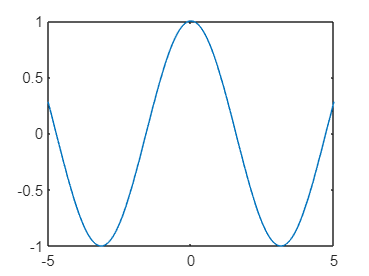

%part b
syms x
fplot(real(exp(1i * x)))

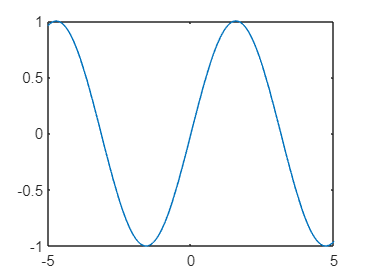

fplot(imag(exp(1i * x)))

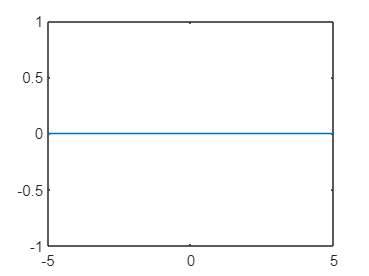

%f(theta) is cos(theta) and g(theta) is sin(theta)
%part c
fplot(cos(x) - real(exp(1i * x)))

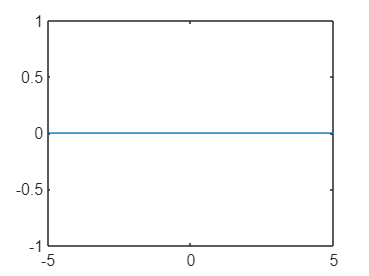

fplot(sin(x) - imag(exp(1i * x)))

%part d
Y = exp(1i*pi) + 1

Y = 0.0000e+00 + 1.2246e-16i